clc,clear
%加载数据
x = load('ex5Linx.dat')

x =    -0.9977
   -0.6957
   -0.4037
   -0.1024
    0.2202
    0.4774
    0.8223


y = load('ex5Liny.dat');
% x m*n
% y m*1
%显示原始数据
plot(x,y,'o','MarkerEdgeColor','b','MarkerFaceColor','r')
hold on
x=[ones(length(x),1) x x.^2 x.^3 x.^4 x.^5]

x =     1.0000   -0.9977    0.9954   -0.9931    0.9908   -0.9885
    1.0000   -0.6957    0.4841   -0.3368    0.2343   -0.1630
    1.0000   -0.4037    0.1630   -0.0658    0.0266   -0.0107
    1.0000   -0.1024    0.0105   -0.0011    0.0001   -0.0000
    1.0000    0.2202    0.0485    0.0107    0.0024    0.0005
    1.0000    0.4774    0.2279    0.1088    0.0520    0.0248
    1.0000    0.8223    0.6762    0.5560    0.4572    0.3759


[m,n]=size(x)

m = 7

n = 6

rm=diag(ones(n,1));
rm(1)=0;
colortype={'g','b','r'};
lambda=[0 1 10];
theta=zeros(n,3);
xrange=linspace(min(x(:,2)),max(x(:,2)))'

xrange =    -0.9977
   -0.9793
   -0.9609
   -0.9425
   -0.9241
   -0.9058
   -0.8874
   -0.8690
   -0.8506
   -0.8322


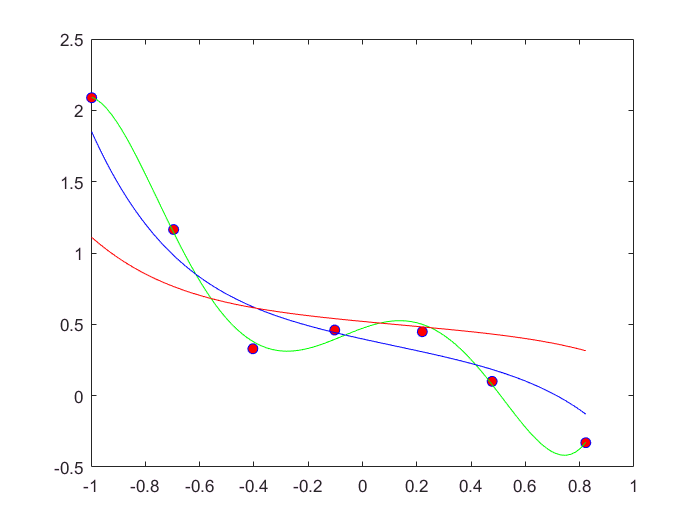

yrange1 =     1.0000   -0.9977    0.9954   -0.9931    0.9908   -0.9885
    1.0000   -0.9793    0.9590   -0.9392    0.9197   -0.9007
    1.0000   -0.9609    0.9234   -0.8873    0.8526   -0.8193
    1.0000   -0.9425    0.8884   -0.8373    0.7892   -0.7438
    1.0000   -0.9241    0.8540   -0.7893    0.7294   -0.6741
    1.0000   -0.9058    0.8204   -0.7431    0.6731   -0.6096
    1.0000   -0.8874    0.7874   -0.6988    0.6201   -0.5502
    1.0000   -0.8690    0.7552   -0.6562    0.5703   -0.4955
    1.0000   -0.8506    0.7235   -0.6155    0.5235   -0.4453
    1.0000   -0.8322    0.6926   -0.5764    0.4797   -0.3992


yrange =     2.0919
    2.0748
    2.0481
    2.0128
    1.9700
    1.9206
    1.8656
    1.8059
    1.7422
    1.6753


yrange1 =     1.0000   -0.9977    0.9954   -0.9931    0.9908   -0.9885
    1.0000   -0.9793    0.9590   -0.9392    0.9197   -0.9007
    1.0000   -0.9609    0.9234   -0.8873    0.8526   -0.8193
    1.0000   -0.9425    0.8884   -0.8373    0.7892   -0.7438
    1.0000   -0.9241    0.8540   -0.7893    0.7294   -0.6741
    1.0000   -0.9058    0.8204   -0.7431    0.6731   -0.6096
    1.0000   -0.8874    0.7874   -0.6988    0.6201   -0.5502
    1.0000   -0.8690    0.7552   -0.6562    0.5703   -0.4955
    1.0000   -0.8506    0.7235   -0.6155    0.5235   -0.4453
    1.0000   -0.8322    0.6926   -0.5764    0.4797   -0.3992


yrange =     1.8501
    1.7740
    1.7016
    1.6328
    1.5673
    1.5052
    1.4461
    1.3900
    1.3367
    1.2861


yrange1 =     1.0000   -0.9977    0.9954   -0.9931    0.9908   -0.9885
    1.0000   -0.9793    0.9590   -0.9392    0.9197   -0.9007
    1.0000   -0.9609    0.9234   -0.8873    0.8526   -0.8193
    1.0000   -0.9425    0.8884   -0.8373    0.7892   -0.7438
    1.0000   -0.9241    0.8540   -0.7893    0.7294   -0.6741
    1.0000   -0.9058    0.8204   -0.7431    0.6731   -0.6096
    1.0000   -0.8874    0.7874   -0.6988    0.6201   -0.5502
    1.0000   -0.8690    0.7552   -0.6562    0.5703   -0.4955
    1.0000   -0.8506    0.7235   -0.6155    0.5235   -0.4453
    1.0000   -0.8322    0.6926   -0.5764    0.4797   -0.3992


yrange =     1.1102
    1.0801
    1.0515
    1.0243
    0.9983
    0.9737
    0.9502
    0.9279
    0.9067
    0.8865


for i=1:3
    theta(:,i)=inv(x'*x+lambda(i).*rm)*x'*y;
yrange1 = [ones(size(xrange)) xrange xrange.^2 xrange.^3,...
        xrange.^4 xrange.^5]
   yrange=yrange1 *theta(:,i)
    plot(xrange,yrange,char(colortype(i)))
    hold on
end